% Natural temperature & thermal conductivity processing
close all
clc
clear
warning off
format long

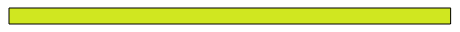

% load data (#4 20220912)
[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end

RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time & heating information
Info.start_test = '2022/09/12  15:20:00'; % apply the test
Info.start_heating = '2022/09/12  17:00:12'; % begain heating
Info.end_heating = '2022/09/12  23:00:00'; % end of heating
Info.end_test = '2022/09/12  23:30:00'; % finish the test
Info.heating_power = 20; % heating power\
clearvars -except Info DTS;

% Extract the data in time
p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

TestProcess1.timeseconds = time_seconds;
TestProcess1.temperature = temperature_processing;
clearvars -except TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating && t_processing<=Info.end_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating);
    end
end

HeatProcess1.timeseconds = time_seconds;
HeatProcess1.temperature = temperature_processing;
clearvars -except HeatProcess1 TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.start_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

NaturalProcess1.timeseconds = time_seconds;
NaturalProcess1.temperature = temperature_processing;
clearvars -except HeatProcess1 TestProcess1 NaturalProcess1 Info DTS;

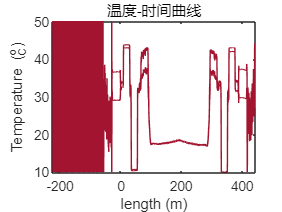

% Check the length
figure(1)
plot(DTS.LAF,TestProcess1.temperature(:,1))
hold on
plot(DTS.LAF,TestProcess1.temperature(:,200))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');


% Borehole [92.323,192.223, 292.124]

% Extract the data in length
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=92.323 && DTS.LAF(k,1)<=192.223
        q = q+1;
        TestProcess2.depth(q,1) = DTS.LAF(k,1)-92.323;
        TestProcess2.temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.223 && DTS.LAF(k,1)<=292.124
        q = q+1;
        TestProcess2.anti_depth(q,1) = 292.124-DTS.LAF(k,1);
        TestProcess2.anti_temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

TestProcess2.anti_depth = flip(TestProcess2.anti_depth);
TestProcess2.anti_temperature = flip(TestProcess2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=92.323 && DTS.LAF(k,1)<=192.223
        q = q+1;
        HeatProcess2.depth(q,1) = DTS.LAF(k,1)-92.323;
        HeatProcess2.temperature(q,:) = HeatProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.223 && DTS.LAF(k,1)<=292.124
        q = q+1;
        HeatProcess2.anti_depth(q,1) = 292.124-DTS.LAF(k,1);
        HeatProcess2.anti_temperature(q,:) = HeatProcess1.temperature(k,:);
    end
end

HeatProcess2.anti_depth = flip(HeatProcess2.anti_depth);
HeatProcess2.anti_temperature = flip(HeatProcess2.anti_temperature);

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=92.323 && DTS.LAF(k,1)<=192.223
        q = q+1;
        NaturalProcess2.depth(q,1) = DTS.LAF(k,1)-92.323;
        NaturalProcess2.temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.223 && DTS.LAF(k,1)<=292.124
        q = q+1;
        NaturalProcess2.anti_depth(q,1) = 292.124-DTS.LAF(k,1);
        NaturalProcess2.anti_temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

NaturalProcess2.anti_depth = flip(NaturalProcess2.anti_depth);
NaturalProcess2.anti_temperature = flip(NaturalProcess2.anti_temperature);

clear k q

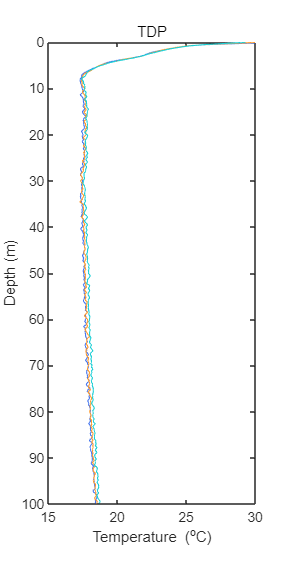

% temperature-depth
figure(2)
color_line = turbo(8);
plot(NaturalProcess2.temperature(:,1),NaturalProcess2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on 
plot(NaturalProcess2.temperature(:,48),NaturalProcess2.depth,"Color",color_line(6,:),'LineWidth',0.75)
hold on
plot(NaturalProcess2.temperature(:,96),NaturalProcess2.depth,"Color",color_line(3,:),'LineWidth',0.75)
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

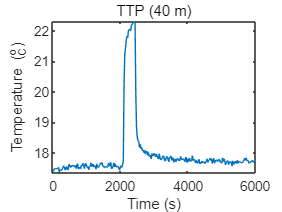

% temperature-time
figure(3)
plot(NaturalProcess1.timeseconds,NaturalProcess2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% select the undistributed data, before 2065.76 s

% data transform
load jintan.mat jintan
jintan.bore4.depth20220912 = NaturalProcess2.depth;
jintan.bore4.temperature202209121540 = mean(NaturalProcess2.temperature(:,18:99),2);
save jintan.mat jintan

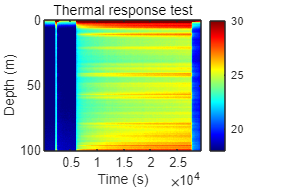

% imagesc
figure(4)
clims = [18 30];
imagesc(TestProcess1.timeseconds,TestProcess2.depth,TestProcess2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("jet")

set(gcf,'unit','centimeters','position',[5 5 18 12]);
clear clims

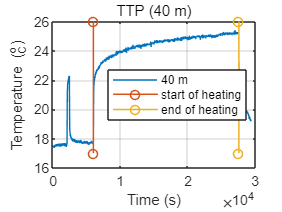

% temperature-time
figure(5)
plot(TestProcess1.timeseconds,TestProcess2.temperature(159,:))
hold on
% ylim([15 45])
% 标注开始加热时间
plot([6000 6000], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% 标注结束加热时间
plot([27600 27600], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating','end of heating','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');
grid on

% pre-thermal conductivity
HeatProcess2.timeseconds = HeatProcess1.timeseconds;
HeatProcess2.lntseconds = log(HeatProcess2.timeseconds);

TC.begin_t = log(3600);
% TC.finish_t = log(21600);
TC.finish_t = log(HeatProcess2.timeseconds(end));

for i = 1:size(HeatProcess2.depth,1)
    p = 0;
    for j = 1:size(HeatProcess2.lntseconds,2)
        if TC.begin_t<HeatProcess2.lntseconds(1,j)&&HeatProcess2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = HeatProcess2.lntseconds(1,j);
            processing_2(i,p) = HeatProcess2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info.heating_power/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

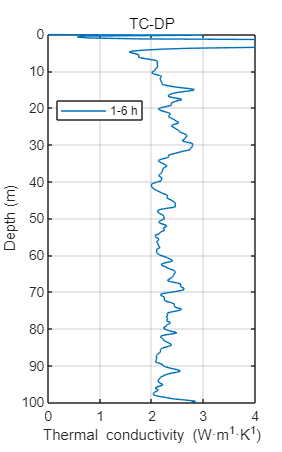

% TC-DP
figure(6)
plot(TC.value,TestProcess2.depth')
legend("1-6 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 4])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on

set(gcf,'unit','centimeters','position',[5 5 10 16]);

% save the processed data
save data_jintan_04_20220912_process_202209152210.mat

% data transform
load jintan.mat jintan
jintan.bore4.thermalConductivity20220912 = TC.value;
save jintan.mat jintan

% next one
clear
clc

% load data (#4 20200813)
[fname,pathn] = uigetfile('*.txt','请选择文件','MultiSelect','on');
fname = cellstr(fname);
[m,n] = size(fname);
filename = char(fname(1,1));
[data,textdata] = importdata([pathn,filename]);

y=length(fname);
startTime=cell(1,y);
for j=1:y
    t=fname(1,j);
    t1=char(t);
    T=t1(4:18);
    T=strrep(T,'_',' ');
    T=[T(1:4),'/',T(5:6),'/',T(7:11),':',T(12:13),':',T(14:end)];%
    Time(:,j)=cellstr(T);
end
startTime = datetime(Time,'InputFormat','yyyy/MM/dd HH:mm:ss');


[m1,~] = size(data.data(:,1));
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    [m2,~] = size(data.data(:,1));
    if m2 < m1
       m1 = m2;
    end
end
txt_data = zeros(m1,n);
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    TMP(:,j) = data.data(1:m1,3);
end

LAF = data.data(1:m1,2);

DTS.startTime=startTime;
DTS.LAF=LAF;
DTS.TMP=TMP;

Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['nzsensing DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time & heating information
Info.start_test = '2020/08/13  09:55:00'; % apply the test
Info.start_heating = '2020/08/13  10:30:00'; % begain heating
Info.end_heating = '2020/08/13  13:30:00'; % end of heating
Info.end_test = '2020/08/13  13:30:00'; % finish the test
Info.heating_power = 10; % heating power
clearvars -except Info DTS;

% Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

TestProcess1.timeseconds = time_seconds;
TestProcess1.temperature = temperature_processing;
clearvars -except TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating && t_processing<=Info.end_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating);
    end
end

HeatProcess1.timeseconds = time_seconds;
HeatProcess1.temperature = temperature_processing;
clearvars -except HeatProcess1 TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.start_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

NaturalProcess1.timeseconds = time_seconds;
NaturalProcess1.temperature = temperature_processing;
clearvars -except HeatProcess1 TestProcess1 NaturalProcess1 Info DTS;

% Check the length
figure(1)
plot(DTS.LAF,TestProcess1.temperature(:,1))
hold on
plot(DTS.LAF,TestProcess1.temperature(:,200))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');

% Borehole [34.52,134.38, 234.25]

% Extract the data in length
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=34.52 && DTS.LAF(k,1)<=134.38
        q = q+1;
        TestProcess2.depth(q,1) = DTS.LAF(k,1)-34.52;
        TestProcess2.temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=134.38 && DTS.LAF(k,1)<=234.25
        q = q+1;
        TestProcess2.anti_depth(q,1) = 234.25-DTS.LAF(k,1);
        TestProcess2.anti_temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

TestProcess2.anti_depth = flip(TestProcess2.anti_depth);
TestProcess2.anti_temperature = flip(TestProcess2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=34.52 && DTS.LAF(k,1)<=134.38
        q = q+1;
        HeatProcess2.depth(q,1) = DTS.LAF(k,1)-34.52;
        HeatProcess2.temperature(q,:) = HeatProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=134.38 && DTS.LAF(k,1)<=234.25
        q = q+1;
        HeatProcess2.anti_depth(q,1) = 234.25-DTS.LAF(k,1);
        HeatProcess2.anti_temperature(q,:) = HeatProcess1.temperature(k,:);
    end
end

HeatProcess2.anti_depth = flip(HeatProcess2.anti_depth);
HeatProcess2.anti_temperature = flip(HeatProcess2.anti_temperature);

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=34.52 && DTS.LAF(k,1)<=134.38
        q = q+1;
        NaturalProcess2.depth(q,1) = DTS.LAF(k,1)-34.52;
        NaturalProcess2.temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=134.38 && DTS.LAF(k,1)<=234.25
        q = q+1;
        NaturalProcess2.anti_depth(q,1) = 234.25-DTS.LAF(k,1);
        NaturalProcess2.anti_temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

NaturalProcess2.anti_depth = flip(NaturalProcess2.anti_depth);
NaturalProcess2.anti_temperature = flip(NaturalProcess2.anti_temperature);

clear k q

% temperature-depth
figure(2)
color_line = turbo(8);
plot(NaturalProcess2.temperature(:,1),NaturalProcess2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on 
plot(NaturalProcess2.temperature(:,11),NaturalProcess2.depth,"Color",color_line(6,:),'LineWidth',0.75)
hold on
plot(NaturalProcess2.temperature(:,end),NaturalProcess2.depth,"Color",color_line(3,:),'LineWidth',0.75)
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");
set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

% temperature-time
figure(3)
plot(NaturalProcess1.timeseconds,NaturalProcess2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% data transform
load jintan.mat jintan
jintan.bore4.depth20200813 = NaturalProcess2.depth;
jintan.bore4.temperature202008131010 = mean(NaturalProcess2.temperature(:,1:54),2);
save jintan.mat jintan

% imagesc
figure(4)
clims = [18 25];
imagesc(TestProcess1.timeseconds,TestProcess2.depth,TestProcess2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("jet")
set(gcf,'unit','centimeters','position',[5 5 18 12]);
clear clims

% temperature-time
figure(5)
plot(TestProcess1.timeseconds,TestProcess2.temperature(99,:))
hold on
% ylim([15 45])
% 标注开始加热时间
plot([2100 2100], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% 标注结束加热时间
plot([12900 12900], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating','end of heating','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');
grid on

% pre-thermal conductivity
HeatProcess2.timeseconds = HeatProcess1.timeseconds;
HeatProcess2.lntseconds = log(HeatProcess2.timeseconds);

TC.begin_t = log(3600);
% TC.finish_t = log(21600);
TC.finish_t = log(HeatProcess2.timeseconds(end));

for i = 1:size(HeatProcess2.depth,1)
    p = 0;
    for j = 1:size(HeatProcess2.lntseconds,2)
        if TC.begin_t<HeatProcess2.lntseconds(1,j)&&HeatProcess2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = HeatProcess2.lntseconds(1,j);
            processing_2(i,p) = HeatProcess2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info.heating_power/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

% TC-DP
figure(6)
plot(TC.value,TestProcess2.depth')
legend("1-3 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 4])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on
set(gcf,'unit','centimeters','position',[5 5 10 16]);

% save the processed data
save data_jintan_04_20200813_process_202209072215.mat

% data transform
load jintan.mat jintan
jintan.bore4.thermalConductivity20200813= TC.value;
save jintan.mat jintan

% next one
clear
clc

% load data (#4 20191203)
[fname,pathn] = uigetfile('*.txt','请选择文件','MultiSelect','on');
fname = cellstr(fname);
[m,n] = size(fname);
filename = char(fname(1,1));
[data,textdata] = importdata([pathn,filename]);

y=length(fname);
startTime=cell(1,y);
for j=1:y
    t=fname(1,j);
    t1=char(t);
    T=t1(4:18);
    T=strrep(T,'_',' ');
    T=[T(1:4),'/',T(5:6),'/',T(7:11),':',T(12:13),':',T(14:end)];%
    Time(:,j)=cellstr(T);
end
startTime = datetime(Time,'InputFormat','yyyy/MM/dd HH:mm:ss');


[m1,~] = size(data.data(:,1));
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    [m2,~] = size(data.data(:,1));
    if m2 < m1
       m1 = m2;
    end
end
txt_data = zeros(m1,n);
for j = 1:n
    filename = char(fname(1,j));
    [data,textdata] = importdata([pathn,filename]);
    TMP(:,j) = data.data(1:m1,3);
end

LAF = data.data(1:m1,2);

DTS.startTime=startTime;
DTS.LAF=LAF;
DTS.TMP=TMP;

Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['nzsensing DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time & heating information
Info.start_test = '2019/12/03  17:00:00'; % apply the test
Info.start_heating1 = '2019/12/04  17:10:00'; % begain heating
Info.end_heating1 = '2019/12/06  17:10:00'; % end of heating
Info.start_heating2 = '2019/12/07  07:43:00'; % begain heating
Info.end_heating2 = '2019/12/09  08:20:00'; % end of heating
Info.end_test = '2019/12/9  20:30:00'; % finish the test
Info.heating_power1 = 40; % heating power
Info.heating_power2 = 80; % heating power
clearvars -except Info DTS;

% Extract the data in time

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

TestProcess1.timeseconds = time_seconds;
TestProcess1.temperature = temperature_processing;
clearvars -except TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating1 && t_processing<=Info.end_heating1
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating1);
    end
end

Heat1Process1.timeseconds = time_seconds;
Heat1Process1.temperature = temperature_processing;
clearvars -except Heat1Process1 TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating2 && t_processing<=Info.end_heating2
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating2);
    end
end

Heat2Process1.timeseconds = time_seconds;
Heat2Process1.temperature = temperature_processing;
clearvars -except Heat1Process1 Heat2Process1 TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.start_heating1
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

NaturalProcess1.timeseconds = time_seconds;
NaturalProcess1.temperature = temperature_processing;
clearvars -except Heat1Process1 Heat2Process1 TestProcess1 NaturalProcess1 Info DTS;

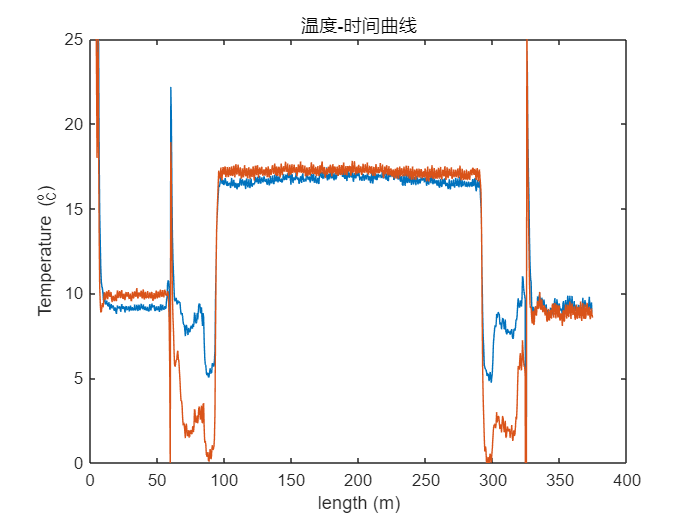

% Check the length
figure(1)
plot(DTS.LAF,TestProcess1.temperature(:,1))
hold on
plot(DTS.LAF,TestProcess1.temperature(:,800))
hold off
ylim([0 25])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');


% Borehole [93.08,192.98, 292.88]

% Extract the data in length
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=93.08 && DTS.LAF(k,1)<=192.98
        q = q+1;
        TestProcess2.depth(q,1) = DTS.LAF(k,1)-93.08;
        TestProcess2.temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.98 && DTS.LAF(k,1)<=292.88
        q = q+1;
        TestProcess2.anti_depth(q,1) = 292.88-DTS.LAF(k,1);
        TestProcess2.anti_temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

TestProcess2.anti_depth = flip(TestProcess2.anti_depth);
TestProcess2.anti_temperature = flip(TestProcess2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=93.08 && DTS.LAF(k,1)<=192.98
        q = q+1;
        Heat1Process2.depth(q,1) = DTS.LAF(k,1)-93.08;
        Heat1Process2.temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.98 && DTS.LAF(k,1)<=292.88
        q = q+1;
        Heat1Process2.anti_depth(q,1) = 292.88-DTS.LAF(k,1);
        Heat1Process2.anti_temperature(q,:) = Heat1Process1.temperature(k,:);
    end
end

Heat1Process2.anti_depth = flip(Heat1Process2.anti_depth);
Heat1Process2.anti_temperature = flip(Heat1Process2.anti_temperature);

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=93.08 && DTS.LAF(k,1)<=192.98
        q = q+1;
        Heat2Process2.depth(q,1) = DTS.LAF(k,1)-93.08;
        Heat2Process2.temperature(q,:) = Heat2Process1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.98 && DTS.LAF(k,1)<=292.88
        q = q+1;
        Heat2Process2.anti_depth(q,1) = 292.88-DTS.LAF(k,1);
        Heat2Process2.anti_temperature(q,:) = Heat2Process1.temperature(k,:);
    end
end

Heat2Process2.anti_depth = flip(Heat2Process2.anti_depth);
Heat2Process2.anti_temperature = flip(Heat2Process2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=93.08 && DTS.LAF(k,1)<=192.98
        q = q+1;
        NaturalProcess2.depth(q,1) = DTS.LAF(k,1)-93.08;
        NaturalProcess2.temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=192.98 && DTS.LAF(k,1)<=292.88
        q = q+1;
        NaturalProcess2.anti_depth(q,1) = 292.88-DTS.LAF(k,1);
        NaturalProcess2.anti_temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

NaturalProcess2.anti_depth = flip(NaturalProcess2.anti_depth);
NaturalProcess2.anti_temperature = flip(NaturalProcess2.anti_temperature);

clear k q

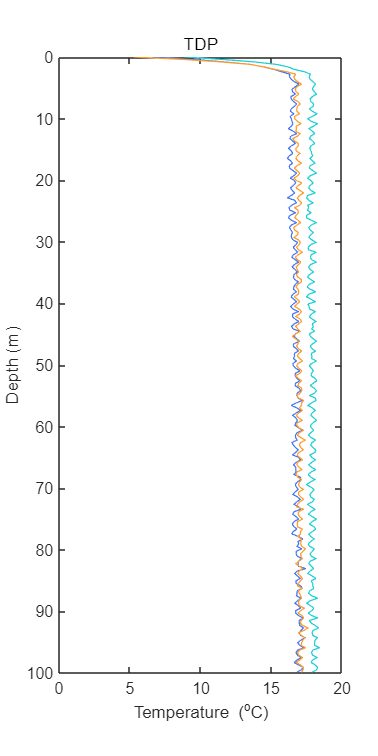

% temperature-depth
figure(2)
color_line = turbo(8);
plot(NaturalProcess2.temperature(:,1),NaturalProcess2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on 
plot(NaturalProcess2.temperature(:,120),NaturalProcess2.depth,"Color",color_line(6,:),'LineWidth',0.75)
hold on
plot(NaturalProcess2.temperature(:,end),NaturalProcess2.depth,"Color",color_line(3,:),'LineWidth',0.75)
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 20])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

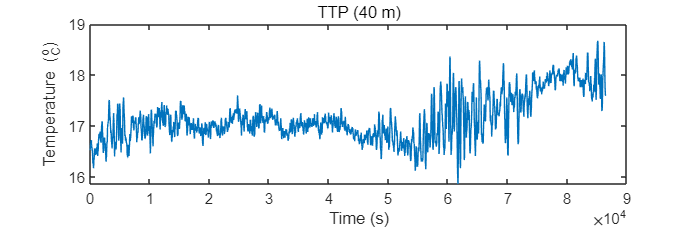

% temperature-time
figure(3)
plot(NaturalProcess1.timeseconds,NaturalProcess2.temperature(101,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% data transform
load jintan.mat jintan
jintan.bore4.depth20191203 = NaturalProcess2.depth;
jintan.bore4.temperature20191203 = mean(NaturalProcess2.temperature(:,1:end),2);
save jintan.mat jintan

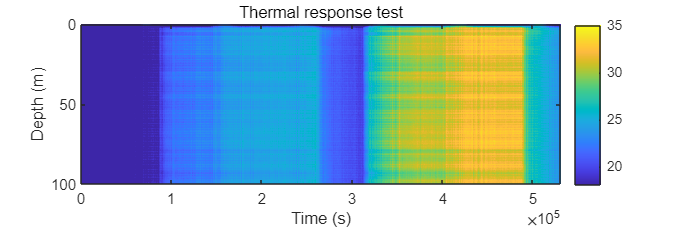

% imagesc
figure(4)
clims = [18 35];
imagesc(TestProcess1.timeseconds,TestProcess2.depth,TestProcess2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("parula")

set(gcf,'unit','centimeters','position',[5 5 36 12]);
clear clims

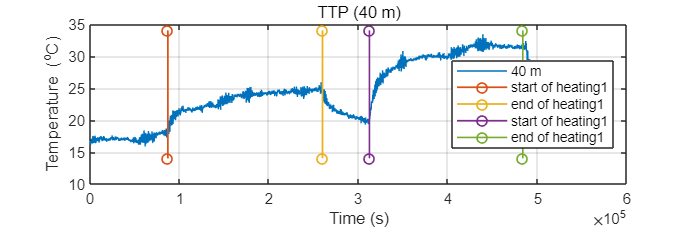

% temperature-time
figure(5)
plot(TestProcess1.timeseconds,TestProcess2.temperature(101,:))
hold on
% ylim([15 45])
% 标注开始加热1时间
plot([87000 87000], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% 标注结束加热1时间
plot([259800 259800], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% 标注开始加热2时间
plot([312180 312180], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% 标注结束加热2时间
plot([483600 483600], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating1','end of heating1','start of heating1','end of heating1','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^oC)');
grid on

set(gcf,'unit','centimeters','position',[5 5 36 12]);

% pre-thermal conductivity (临时20220908)
Heat2Process2.timeseconds = Heat2Process1.timeseconds;
Heat2Process2.lntseconds = log(Heat2Process2.timeseconds);

TC.begin_t = log(3600);
% TC.finish_t = log(21600);
TC.finish_t = log(Heat2Process2.timeseconds(end));

for i = 1:size(Heat2Process2.depth,1)
    p = 0;
    for j = 1:size(Heat2Process2.lntseconds,2)
        if TC.begin_t<Heat2Process2.lntseconds(1,j)&&Heat2Process2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = Heat2Process2.lntseconds(1,j);
            processing_2(i,p) = Heat2Process2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info.heating_power2/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

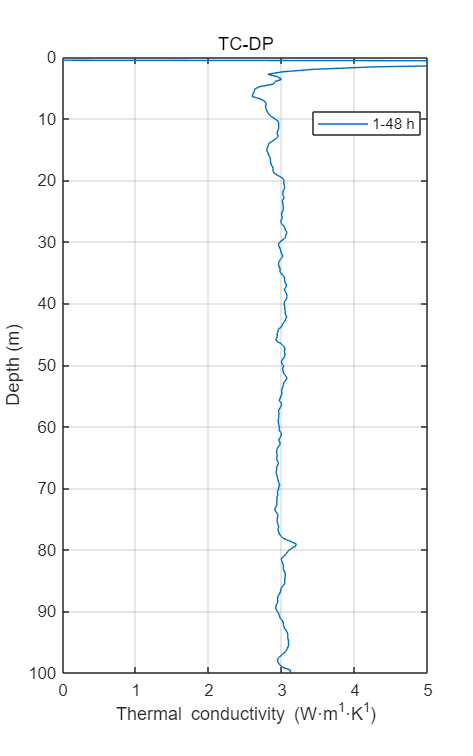

% TC-DP
figure(6)
plot(TC.value,TestProcess2.depth')
legend("1-48 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 5])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on

set(gcf,'unit','centimeters','position',[5 5 10 16]);

% save the processed data
save data_jintan_04_20191203_process_202209081450.mat

% data transform
load jintan.mat jintan
jintan.bore4.thermalConductivity20191207= TC.value;
save jintan.mat jintan

% next one
clear
clc

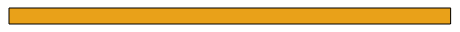

% load data (#2 20220914)
[filename,filepath] = uigetfile({'*.xml','silixa XML files(*.xml)'},"MultiSelect","on");
n = length(filename);
dom = xmlread([filepath,char(filename(1))]);
datas = dom.getElementsByTagName('data');
m = datas.getLength;
startDateTimeStrings = strings(1,n);
RT = strings(1,n);
RTP1 = strings(1,n);
RTP2 = strings(1,n);

LAF = zeros(m,n); % length along fiber
ST = zeros(m,n); % Stokes intensity
AST = zeros(m,n); % anti-Stokes intensity
REV_ST = zeros(m,n); % reverse Stokes intensity
REV_AST = zeros(m,n); % reverse anti-Stokes intensity
TMP = zeros(m,n); % DTS temperature

progressbar
for j=1:n
    dom=xmlread([filepath,char(filename(j))]);
    datas=dom.getElementsByTagName('data');
    % m=datas.getLength;
    startDateTime=dom.getElementsByTagName('startDateTimeIndex');
    startDateTimeStrings(1,j)=char(startDateTime.item(0).getFirstChild.getData);
    startTime = datetime(startDateTimeStrings,'InputFormat','uuuu-MM-dd''T''HH:mm:ss.SSSXXXX','TimeZone','UTC+8');
    referenceTemperature = dom.getElementsByTagName('referenceTemperature');
    RT(1,j)=char(referenceTemperature.item(0).getFirstChild.getData);
    probe1Temperature = dom.getElementsByTagName('probe1Temperature');
    RTP1(1,j)=char(probe1Temperature.item(0).getFirstChild.getData);
    probe2Temperature = dom.getElementsByTagName('probe2Temperature');
    RTP2(1,j)=char(probe2Temperature.item(0).getFirstChild.getData);
    
    for i=0:m-1 % XML中索引从0开始
        dataValues=char(datas.item(i).getFirstChild.getData); % 读取节点下的数据
        dataValues=strip(dataValues); % 删除首尾空白字符
        dataValue=split(dataValues,','); % 以','分割字符串
        LAF(i+1,j)=str2double(cell2mat(dataValue(1))); % 保存各数据
        ST(i+1,j)=str2double(cell2mat(dataValue(2)));
        AST(i+1,j)=str2double(cell2mat(dataValue(3)));
        REV_ST(i+1,j)=str2double(cell2mat(dataValue(4)));
        REV_AST(i+1,j)=str2double(cell2mat(dataValue(5)));
        TMP(i+1,j)=str2double(cell2mat(dataValue(6)));
    end
    progressbar(j/n)
end

RT = str2double(RT);
RTP1 = str2double(RTP1);
RTP2 = str2double(RTP2);

DTS.startTime=startTime;
DTS.RT=RT;
DTS.RTP1=RTP1;
DTS.RTP2=RTP2;
DTS.LAF=LAF;
DTS.ST=ST;
DTS.AST=AST;
DTS.REV_ST=REV_ST;
DTS.REV_AST=REV_AST;
DTS.TMP=TMP;

% [savename,savepath]=uiputfile('*.mat');
Tstart=replace(replace(replace(char(startTime(1)),'-',''),' ',''),':','');
Tend=replace(replace(replace(char(startTime(end)),'-',''),' ',''),':','');
savename=['Ultima DTS_',Tstart,'_',Tend,'.mat'];
save(savename,'DTS');

clearvars -except DTS;

% time & heating information
Info.start_test = '2022/09/14  14:20:00'; % apply the test
Info.start_heating = '2022/09/14  15:30:00'; % begain heating
Info.end_heating = '2022/09/14  21:30:00'; % end of heating
Info.end_test = '2022/09/14  22:00:00'; % finish the test
Info.heating_power = 20; % heating power
clearvars -except Info DTS;

% Extract the data in time
p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.end_test
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

TestProcess1.timeseconds = time_seconds;
TestProcess1.temperature = temperature_processing;
clearvars -except TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_heating && t_processing<=Info.end_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_heating);
    end
end

HeatProcess1.timeseconds = time_seconds;
HeatProcess1.temperature = temperature_processing;
clearvars -except HeatProcess1 TestProcess1 Info DTS;

p = 0;
for i = 1:length(DTS.startTime)
    t_processing = DTS.startTime(1,i);
    if t_processing>=Info.start_test && t_processing<=Info.start_heating
        p = p+1;
        date(1,p) = DTS.startTime(1,i);
        temperature_processing(:,p) = DTS.TMP(1:end,i);
        t_processed = date(1,p);
        t_processed = char(t_processed);
        t_processed = datetime(t_processing,'InputFormat','yyyy/MM/dd HH:mm:ss');
        time_seconds(1,p) = seconds(t_processed-Info.start_test);
    end
end

NaturalProcess1.timeseconds = time_seconds;
NaturalProcess1.temperature = temperature_processing;
clearvars -except HeatProcess1 TestProcess1 NaturalProcess1 Info DTS;

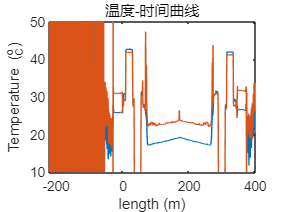

% Check the length
figure(1)
plot(DTS.LAF,TestProcess1.temperature(:,1))
hold on
plot(DTS.LAF,TestProcess1.temperature(:,200))
hold off
ylim([10 50])
title('温度-时间曲线')
xlabel('length (m)');
ylabel('Temperature (^o_C)');


% Borehole [71.987,171.633, 271.279]

% Extract the data in length
q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=71.987 && DTS.LAF(k,1)<=171.633
        q = q+1;
        TestProcess2.depth(q,1) = DTS.LAF(k,1)-71.987;
        TestProcess2.temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.633 && DTS.LAF(k,1)<=271.279
        q = q+1;
        TestProcess2.anti_depth(q,1) = 271.279-DTS.LAF(k,1);
        TestProcess2.anti_temperature(q,:) = TestProcess1.temperature(k,:);
    end
end

TestProcess2.anti_depth = flip(TestProcess2.anti_depth);
TestProcess2.anti_temperature = flip(TestProcess2.anti_temperature);


q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=71.987 && DTS.LAF(k,1)<=171.633
        q = q+1;
        HeatProcess2.depth(q,1) = DTS.LAF(k,1)-71.987;
        HeatProcess2.temperature(q,:) = HeatProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.633 && DTS.LAF(k,1)<=271.279
        q = q+1;
        HeatProcess2.anti_depth(q,1) = 271.279-DTS.LAF(k,1);
        HeatProcess2.anti_temperature(q,:) = HeatProcess1.temperature(k,:);
    end
end

HeatProcess2.anti_depth = flip(HeatProcess2.anti_depth);
HeatProcess2.anti_temperature = flip(HeatProcess2.anti_temperature);

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=71.987 && DTS.LAF(k,1)<=171.633
        q = q+1;
        NaturalProcess2.depth(q,1) = DTS.LAF(k,1)-71.987;
        NaturalProcess2.temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

q = 0;
for k = 1:size(DTS.LAF,1)
    if DTS.LAF(k,1)>=171.633 && DTS.LAF(k,1)<=271.279
        q = q+1;
        NaturalProcess2.anti_depth(q,1) = 271.279-DTS.LAF(k,1);
        NaturalProcess2.anti_temperature(q,:) = NaturalProcess1.temperature(k,:);
    end
end

NaturalProcess2.anti_depth = flip(NaturalProcess2.anti_depth);
NaturalProcess2.anti_temperature = flip(NaturalProcess2.anti_temperature);

clear k q

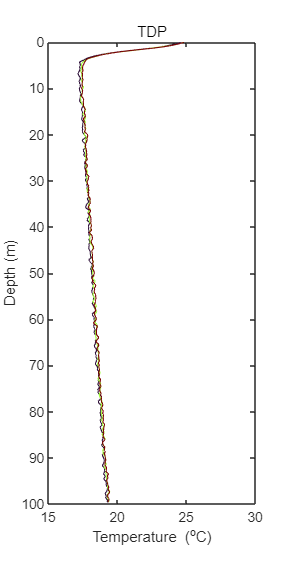

% temperature-depth
figure(2)
color_line = turbo(3);
plot(NaturalProcess2.temperature(:,1),NaturalProcess2.depth,"Color",color_line(1,:),'LineWidth',0.75)
hold on 
plot(NaturalProcess2.temperature(:,54),NaturalProcess2.depth,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(NaturalProcess2.temperature(:,109),NaturalProcess2.depth,"Color",color_line(3,:),'LineWidth',0.75)
hold off 
set(gca,'YDir','reverse');
ylim([0 100])
xlim([15 30])
title('TDP')
ylabel('Depth (m)');
xlabel('Temperature (^oC)',"Clipping","on");

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line

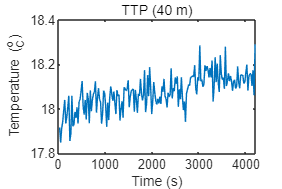

% temperature-time
figure(3)
plot(NaturalProcess1.timeseconds,NaturalProcess2.temperature(159,:))
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');

% select the undistributed data, before 2065.76 s

% data transform
load jintan.mat jintan
jintan.bore2.depth20220914 = NaturalProcess2.depth;
jintan.bore2.temperature202209141440 = mean(NaturalProcess2.temperature(:,1:109),2);
save jintan.mat jintan

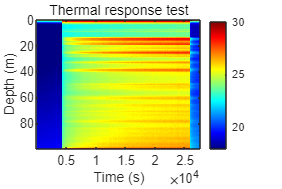

% imagesc
figure(4)
clims = [18 30];
imagesc(TestProcess1.timeseconds,TestProcess2.depth,TestProcess2.temperature,clims)
title('Thermal response test')
xlabel('Time (s)');
ylabel('Depth (m)');
colorbar
colormap("jet")
set(gcf,'unit','centimeters','position',[5 5 18 12]);

clear clims

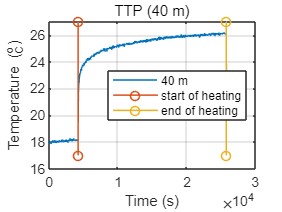

% temperature-time
figure(5)
plot(TestProcess1.timeseconds,TestProcess2.temperature(159,:))
hold on
% ylim([15 45])
% 标注开始加热时间
plot([4200 4200], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold on
% 标注结束加热时间
plot([25800 25800], get(gca, 'YLim'), '-o', 'LineWidth', 1)
hold off
legend('40 m','start of heating','end of heating','Location','Southeast',"location","east")
title('TTP (40 m)')
xlabel('Time (s)');
ylabel('Temperature (^o_C)');
grid on

% pre-thermal conductivity
HeatProcess2.timeseconds = HeatProcess1.timeseconds;
HeatProcess2.lntseconds = log(HeatProcess2.timeseconds);

TC.begin_t = log(3600);
% TC.finish_t = log(21600);
TC.finish_t = log(HeatProcess2.timeseconds(end));

for i = 1:size(HeatProcess2.depth,1)
    p = 0;
    for j = 1:size(HeatProcess2.lntseconds,2)
        if TC.begin_t<HeatProcess2.lntseconds(1,j)&&HeatProcess2.lntseconds (1,j)<TC.finish_t
            p = p+1;
            processing_1(i,p) = HeatProcess2.lntseconds(1,j);
            processing_2(i,p) = HeatProcess2.temperature(i,j);
        end
    end
    lxx = sum((processing_1(i,:)-mean(processing_1(i,:))).^2);
    lxy = sum((processing_1(i,:)-mean(processing_1(i,:))).*(processing_2(i,:)-mean(processing_2(i,:))));
    processing_3(i) = lxy/lxx;
    TC.value(i) = Info.heating_power/(4*pi*processing_3(i));
    clear processing_1
    clear processing_2
    clear processing_3
end
clear i j lxx lxy p

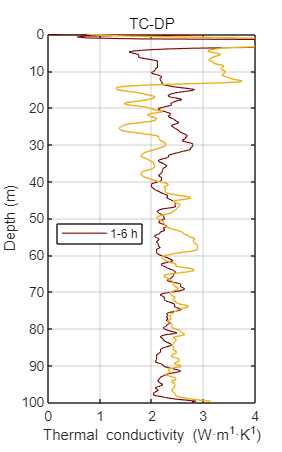

% TC-DP
figure(6)
plot(TC.value,TestProcess2.depth')
legend("1-6 h",Location="best")
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 4])
title('TC-DP')
xlabel('Thermal conductivity (W·m^-^1·K^-^1)');
ylabel('Depth (m)');
grid on

set(gcf,'unit','centimeters','position',[5 5 10 16]);

% save the processed data
save data_jintan_02_20220914_process_2022091522310.mat

% data transform
load jintan.mat jintan
jintan.bore2.thermalConductivity20220914 = TC.value;
save jintan.mat jintan

% next one
clear
clc

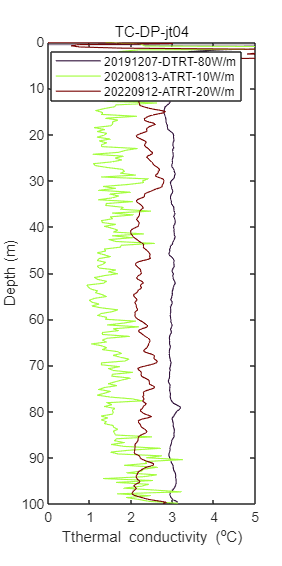

% update
load jintan.mat
figure(7)
color_line = turbo(3);
plot(jintan.bore4.thermalConductivity20191207,jintan.bore4.depth20191203,"Color",color_line(1,:),'LineWidth',0.75)
hold on
plot(jintan.bore4.thermalConductivity20200813,jintan.bore4.depth20200813,"Color",color_line(2,:),'LineWidth',0.75)
hold on
plot(jintan.bore4.thermalConductivity20220912,jintan.bore4.depth20220912,"Color",color_line(3,:),'LineWidth',0.75)
hold off
set(gca,'YDir','reverse');
ylim([0 100])
xlim([0 5])
title('TC-DP-jt04')
ylabel('Depth (m)');
xlabel('Tthermal conductivity (^oC)',"Clipping","on");
legend('20191207-DTRT-80W/m','20200813-ATRT-10W/m','20220912-ATRT-20W/m',location='best')

set(gcf,'unit','centimeters','position',[5 5 8 16]);
clear color_line